num_unique_matches = @(N) factorial(N)/factorial(N/2)/power(2,N/2);

desired_N = 16;

N = 2;
unique_matches = {[1; 2]};

num_recursions = (desired_N-2)/2;
for recursion_number = 1:num_recursions
    N_new = N + 2;
    unique_matches_new = cell(1,factorial(N_new)/power(2,N_new/2)/factorial(N_new/2));
    possible_numbers = 2:N_new;

    for previous_match_set = 1:length(unique_matches)

        for paired_with_one = possible_numbers
            remaining_numbers = possible_numbers(possible_numbers~=paired_with_one);

            new_match_number = (paired_with_one-2)*length(unique_matches)+previous_match_set;

            new_match_matrix = nan(2,N_new/2);
            new_match_matrix(:,1) = [1; paired_with_one];
            
            for rr = 1:2
                for cc = 2:N_new/2
                    new_match_matrix(rr,cc) = remaining_numbers(unique_matches{previous_match_set}(rr,cc-1));
                end
            end
            unique_matches_new{new_match_number} = new_match_matrix;
        end
    end
    unique_matches = unique_matches_new;
    N = N_new;
end

N

N = 16

% Generating Unique Match Profitability Data

% % Bet Parameters
% M = 1;
% x = 2;
% 
% % Parallel Pool Set Up
% p = gcp('nocreate');
% if isempty(p)
%     pool = parpool("Processes");
%     num_workers = pool.NumWorkers;
% else
%     num_workers = p.NumWorkers;
% end
% 
% % Data Generation
% parfor index = 1:4
%     for trial_number = 25*(index-1)+(25)
%         trial_data_path = 'C:\Users\wynga\OneDrive\Desktop\PhD_Research\Data\Unique Match Results';
% 
%         p_values = sort(rand(1,N)); %Generating P Values from Uniform Distribution over [0, 1]
% 
%         unique_set_of_pairs_profits = zeros(1,length(unique_matches));
%         for unique_set_of_pairs_index = 1:length(unique_matches)
%             unique_set_of_matches = unique_matches{unique_set_of_pairs_index};
%             for pair_index = 1:(N/2)
%                 p1 = p_values(unique_set_of_matches(1,pair_index));
%                 p2 = p_values(unique_set_of_matches(2,pair_index));
%                 peer_bet = peer_to_peer(p1,p2,M,x);
%                 unique_set_of_pairs_profits(unique_set_of_pairs_index) = unique_set_of_pairs_profits(unique_set_of_pairs_index) + peer_bet.profit;
%             end
%         end
% 
%         outside_in_profit = 0;
%         for pair_index = 1:(N/2)
%             p1 = p_values(pair_index);
%             p2 = p_values(N+1-pair_index);
%             peer_bet = peer_to_peer(p1,p2,M,x);
%             outside_in_profit = outside_in_profit + peer_bet.profit;
%         end
% 
%         temporary_struct = struct("unique_set_of_pairs_profit",unique_set_of_pairs_profits,"outside_in_profit",outside_in_profit);
%         save(horzcat(trial_data_path,'\',sprintf('Trial Set %i',index),'\',sprintf('Trial %i',trial_number)),"-fromstruct",temporary_struct)
% 
%     end
% end


% Loading and Working With Data

all_unique_set_of_pairs_profits = nan(100,length(unique_matches));
all_outside_in_profits = nan(1,100);

for trial_number = 1:100
    index = floor((trial_number-1)/25)+1;
    trial_data_path = 'C:\Users\wynga\OneDrive\Desktop\PhD_Research\Data\Unique Match Results'; 
    loaded_data = load(horzcat(trial_data_path,'\',sprintf('Trial Set %i',index),'\',sprintf('Trial %i',trial_number)));
    all_unique_set_of_pairs_profits(trial_number,:) = loaded_data.unique_set_of_pairs_profit;
    all_outside_in_profits(trial_number) = loaded_data.outside_in_profit;
end

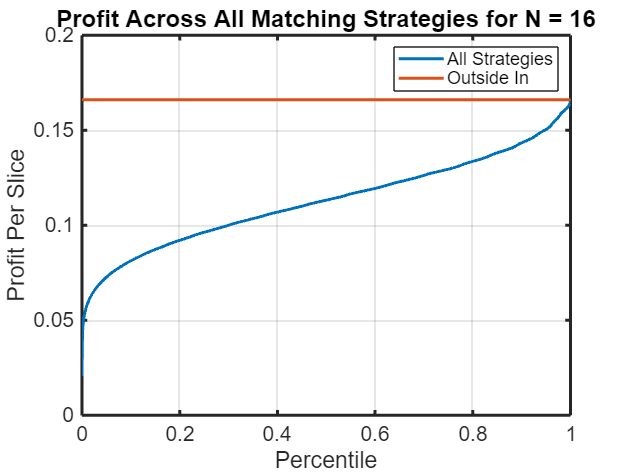

% Average Strategy Profits Across 100 Trials
strategy_profits = sum(all_unique_set_of_pairs_profits,1)/100;

% Profit per Player
strategy_profits = strategy_profits/N;
outside_in_profits = all_outside_in_profits/N;

plot((0:(length(strategy_profits)-1))/length(strategy_profits),sort(strategy_profits))
hold on
y_outside_in = mean(outside_in_profits);
plot([0,1],[y_outside_in,y_outside_in])
hold off
ylim([0 .2])
legend({'All Strategies','Outside In'},'FontSize',12)
xlabel('Percentile')
ylabel('Profit Per Slice')
title(sprintf('Profit Across All Matching Strategies for N = %i',N))
sexy_plot


% Number of Strategies with Better Averages Across Trials
sum(strategy_profits>mean(outside_in_profits))

ans = 14

outside_in_percentile = 1-sum(strategy_profits>mean(outside_in_profits))/length(strategy_profits)

outside_in_percentile = 1.0000


% Best Strategy vs. Outside In and Split n' Pair
max(strategy_profits)

ans = 0.1661

mean(outside_in_profits)

ans = 0.1660

max(strategy_profits)/mean(outside_in_profits)

ans = 1.0009

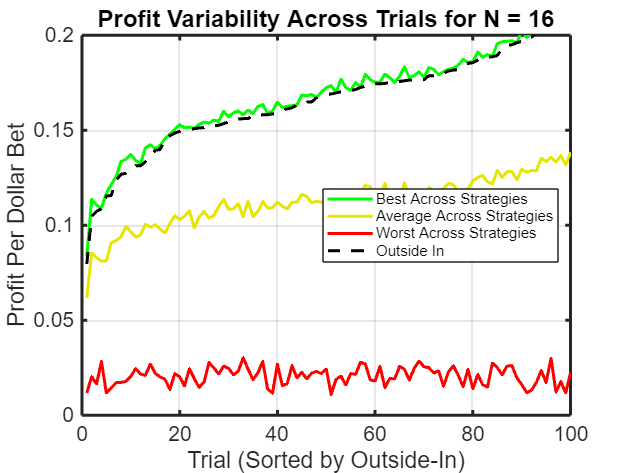

% Variability Across Trials
min_profits = min(all_unique_set_of_pairs_profits,[],2)/N;
mean_profits = mean(all_unique_set_of_pairs_profits,2)/N;
max_profits = max(all_unique_set_of_pairs_profits,[],2)/N;
[~,sort_indeces] = sort(outside_in_profits);

plot(1:100,max_profits(sort_indeces),'Color',[0 1 0])
hold on
plot(1:100,mean_profits(sort_indeces),'Color',[.9 .9 0])
plot(1:100,min_profits(sort_indeces),'Color',[1 0 0])
plot(1:100,outside_in_profits(sort_indeces),'LineStyle','--','Color',[0 0 0])
hold off
ylim([0 .2])
legend({'Best Across Strategies','Average Across Strategies','Worst Across Strategies','Outside In'},'FontSize',10,'Location','east')
xlabel('Trial (Sorted by Outside-In)')
ylabel('Profit Per Dollar Bet')
title(sprintf('Profit Variability Across Trials for N = %i',N))
sexy_plot